% Loading in data (Salinas A datacube and ground truths)
load("data/SalinasA_corrected.mat");
load("data/SalinasA_gt.mat");

% Removing unlabeled data from datacube
keepCube = zeros(size(salinasA_corrected,1),size(salinasA_corrected,2),size(salinasA_corrected,3));
for i = 1:size(keepCube,1)
    for j = 1:size(keepCube,2)
        if(salinasA_gt(i,j) > 0)
            keepCube(i,j,:) = salinasA_corrected(i,j,:);
        end
    end
end

% Reshaping the datacube samples into a matrix for the K means algorithm to
% run through. This also creates a label set and spatial location set
vectorSet = cell(1,5348);
labelSet = cell(1,5348);
spatialSet = cell(1,5348);
index = 1;
for i = 1:size(keepCube,1)
    for j = 1:size(keepCube,2)
        if(salinasA_gt(i,j) > 0)
            vector = reshape(keepCube(i,j,:),1,204);
            vectorSet{index} = vector;
            labelSet{index} = salinasA_gt(i,j);
            spatialSet{index} = [i,j];
            index = index + 1;
        end
    end
end

% Reconverting back into matrix
salinasAData = cell2mat(vectorSet);
salinasAData = reshape(salinasAData,204,5348);

salinasALabels = cell2mat(labelSet);

salinasAPixels = cell2mat(spatialSet);
salinasAPixels = reshape(salinasAPixels,2,5348);

% Shuffling data for testing
[~,randIndeces] = sort(randn(1,5348));
salinasAData_shuffled = [salinasAData(:,randIndeces(1:end))];
salinasALabels_shuffled = [salinasALabels(randIndeces(1:end))];
salinasAPixels_shuffled = [salinasAPixels(:,randIndeces(1:end))];

% Saving data
save("data/salinasAData.mat","salinasAData");
save("data/salinasALabels.mat","salinasALabels");
save("data/salinasAPixels.mat","salinasAPixels");
save("data/salinasAData_shuffled.mat","salinasAData_shuffled");
save("data/salinasALabels_shuffled.mat","salinasALabels_shuffled");
save("data/salinasAPixels_shuffled.mat","salinasAPixels_shuffled");

% Post Processing Testing
load("results/serialKResults.mat");
load("results/serialKResults_shuffled.mat");

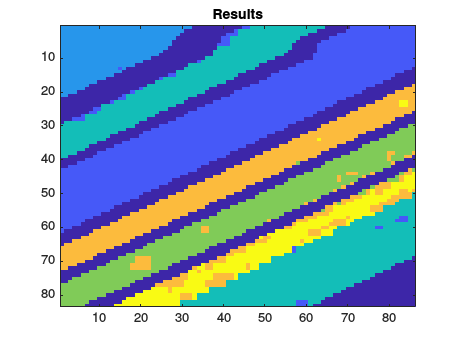

resultsImage = zeros(83,86);
resultsImage_shuffled = zeros(83,86);
for i = 1:5348
    resultsImage(salinasAPixels(1,i),salinasAPixels(2,i)) = salinasAAssignments(i);
    resultsImage_shuffled(salinasAPixels_shuffled(1,i),salinasAPixels_shuffled(2,i)) = salinasAAssignments_shuffled(i);
end
imagesc(resultsImage); title("Results");

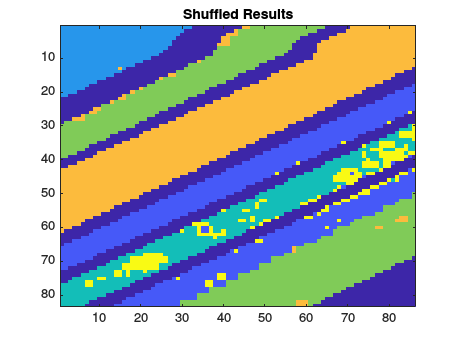

imagesc(resultsImage_shuffled); title("Shuffled Results");